# 收益率和价格

读取时间序列: 中国平安(601318) 2019.8.1~2019.9.30 收盘价.

price = readtable("Data_601318_2019Aug_Sept.csv");

画出收盘价序列图.

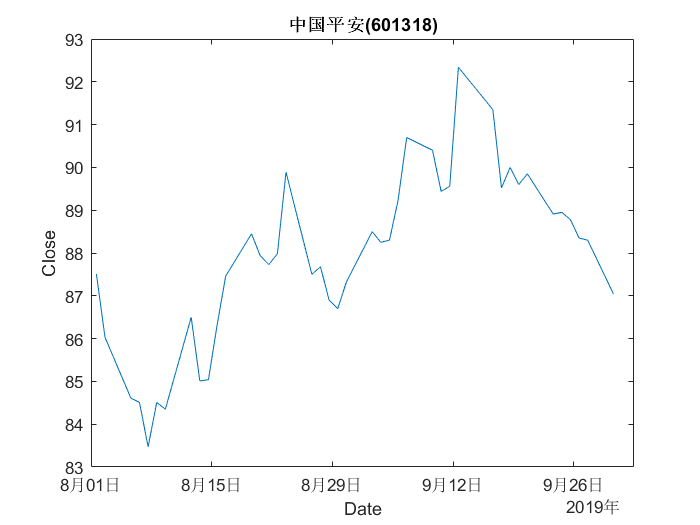

% convert string to datetime
price.time = datetime(price.time);

plot(price.time, price.close);
ylabel("Close");
xlabel("Date");
title("中国平安(601318)");

画出收益率序列图: 简单收益率 & 对数收益率

intr = diff(price.close) ./ price.close(2:end);
plot(price.time(2:end), intr); hold on;
ln_intr = diff(log(price.close));
plot(price.time(2:end), ln_intr);
built_intr = tick2ret(price.close, [], "Simple");

plot(price.time(2:end), built_intr);
built_ln_intr = tick2ret(price.close, [], "Continuous");

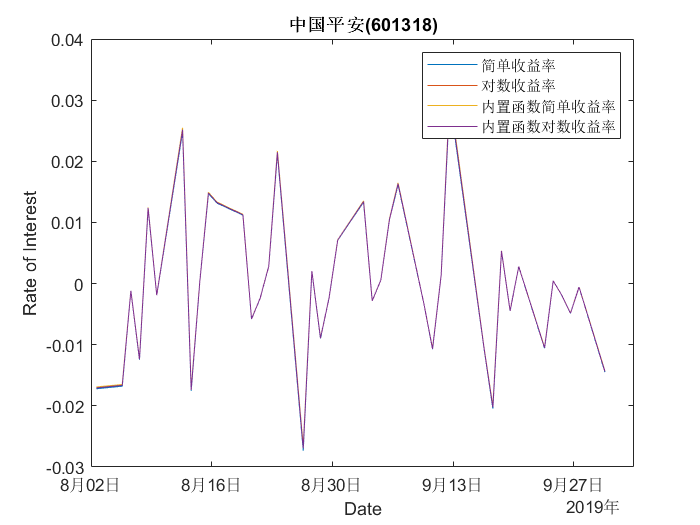

plot(price.time(2:end), built_ln_intr);
legend(["简单收益率", "对数收益率", "内置函数简单收益率", "内置函数对数收益率"]);
ylabel("Rate of Interest");
xlabel("Date");
title("中国平安(601318)");
hold off;

# 协方差和相关性系数

读取时间序列, 3个股票 2019.8.1~2019.9.30 的收盘价.

price = readtable("Data_3stock_2019_Aug_Sept.csv", "DatetimeType", "text");

price = table2array(price(:, 2:end));

求协方差:

cov_ = cov(price);
cov_

cov_ =     4.1251    0.3982    2.0880
    0.3982    0.1461    0.4279
    2.0880    0.4279    2.6270


求相关性系数:

corr_ = corrcoef(price);
corr_

corr_ =     1.0000    0.5130    0.6343
    0.5130    1.0000    0.6907
    0.6343    0.6907    1.0000


标准差:

sigma_ = std(price);
sigma_

sigma_ =     2.0310    0.3822    1.6208


协方差 -> 相关性系数

[sigma_1, corr_1] = cov2corr(cov_);
sigma_1, corr_1

sigma_1 =     2.0310    0.3822    1.6208


corr_1 =     1.0000    0.5130    0.6343
    0.5130    1.0000    0.6907
    0.6343    0.6907    1.0000


相关性系数 -> 协方差

cov_1 = corr2cov(sigma_, corr_);
cov_1

cov_1 =     4.1251    0.3982    2.0880
    0.3982    0.1461    0.4279
    2.0880    0.4279    2.6270
